# ASEN 2003 Lab 1 Code

By Tristan Workman, Max Martinez, Tyler Schwinck, and Drew Miller

Last modified 1/28/2021

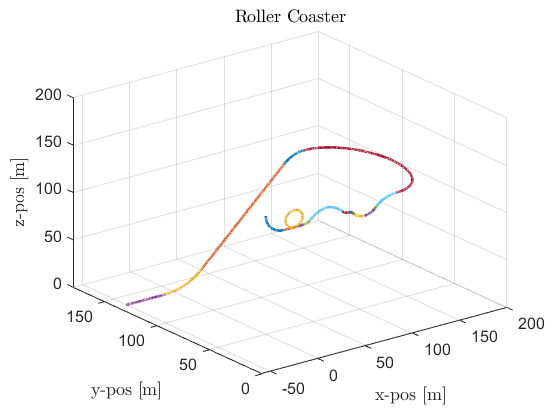

% Objective: Creating a roller coaster track using parametric equations,
% and determine the velocity at any point along the track, as well as the G
% force experienced in any of the cartesian directions (X, Y, Z).

% Assuming: Point mass for cart, no non-conservative forces, cart never
% leaves track, assume riders possess the ability of teleportation.

% Creates plot for track, showing the general path.
[x2, y2, z2, vel2, Gx2, Gy2, Gz2] = section2(0,50,125);
plot3(x2,y2,z2,"LineWidth",2)
title("Roller Coaster")
set(0,'defaultTextInterpreter','latex')
set(gca,'FontSize',12)
xlabel("x-pos [m]")
ylabel("y-pos [m]")
zlabel("z-pos [m]")
xlim([-60 200])
ylim([0 180])
zlim([0 200])
grid on
hold on

% Each subsequent function call/plot adds another section of track
[x3, y3, z3, vel3, Gx3, Gy3, Gz3] = section3(x2(end),y2(end),z2(end),10);
plot3(x3,y3,z3,"LineWidth",2)
hold on
[x4,y4,z4,vel4,Gx4,Gy4,Gz4] = loopPath(x3(end),y3(end),z3(end),9,1);
plot3(x4,y4,z4,"LineWidth",2)
[x5, y5, z5, vel5, Gx5, Gy5, Gz5] = section3(x4(end),y4(end),z4(end),10);
plot3(x5,y5,z5,"LineWidth",2)
[x6, y6, z6, vel6, Gx6, Gy6, Gz6] = launch(x5(end),y5(end),z5(end),10);
plot3(x6,y6,z6,"LineWidth",2)
parabolicPos = [x6(end),y6(end),z6(end)];
parabolicVel = [vel6(end)*sqrt(2)/2,0,vel6(end)*sqrt(2)/2];
[x7, y7, z7, vel7, Gx7, Gy7, Gz7, vf] = Parabola(parabolicVel,parabolicPos);
plot3(x7,y7,z7,"LineWidth",2)
[x8, y8, z8, vel8, Gx8, Gy8, Gz8] = landing1(x7(end),y7(end),z7(end),10);
plot3(x8,y8,z8,"LineWidth",2)
[x9, y9, z9, vel9, Gx9, Gy9, Gz9] = section1(x8(end),y8(end),z8(end),5);
plot3(x9,y9,z9,"LineWidth",2)
[x10, y10, z10, vel10, Gx10, Gy10, Gz10] = linearDown(x9(end),y9(end),z9(end),2);
plot3(x10,y10,z10,"LineWidth",2)
[x11, y11, z11, vel11, Gx11, Gy11, Gz11] = landing2(x10(end),y10(end),z10(end),15);
plot3(x11,y11,z11,"LineWidth",2)
[x12, y12, z12, vel12, Gx12, Gy12, Gz12] = launch2(x11(end),y11(end),z11(end),15);
plot3(x12, y12, z12,"LineWidth",2)
[x13, y13, z13, vel13, Gx13, Gy13, Gz13] = linearUp(x12(end), y12(end), z12(end),2);
plot3(x13, y13, z13,"LineWidth",2)
[x14, y14, z14, vel14, Gx14, Gy14, Gz14] = section4(x13(end), y13(end), z13(end),30);
plot3(x14, y14, z14,"LineWidth",2)
[x15, y15, z15, vel15, Gx15, Gy15, Gz15] = bankedTurn(x14(end), y14(end), z14(end), vel14(end), 30);
plot3(x15, y15, z15,"LineWidth",2)
[x16, y16, z16, vel16, Gx16, Gy16, Gz16] = sectionDown(x15(end), y15(end), z15(end),30);
plot3(x16, y16, z16,"LineWidth",2)
[x17, y17, z17, vel17, Gx17, Gy17, Gz17] = linearDown2(x16(end),y16(end),z16(end),(86.2364+1.1711));
plot3(x17,y17,z17,"LineWidth",2)
[x18, y18, z18, vel18, Gx18, Gy18, Gz18] = landing3(x17(end),y17(end),z17(end),55);
plot3(x18,y18,z18,"LineWidth",2)
[x19, y19, z19, vel19, Gx19, Gy19, Gz19] = braking(x18(end),y18(end),z18(end),vel18(end));
plot3(x19,y19,z19,"LineWidth",2)
hold off

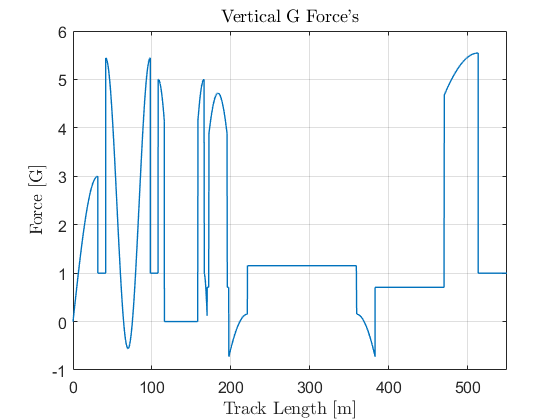


% Plotting Z G forces (perpendicular vertically to the cart)
plot([Gz2 Gz3 Gz4 Gz5 Gz6 Gz7 Gz8 Gz9 Gz10 Gz11 Gz12 Gz13 Gz14 Gz15 Gz16 Gz17 Gz18 Gz19],"LineWidth",1)
title("Vertical G Force's")
set(gca,'FontSize',12)
xlabel("Track Length [m]")
ylabel("Force [G]")
xlim([0 55000])
grid on
xticklabels([0 100 200 300 400 500])
hold off

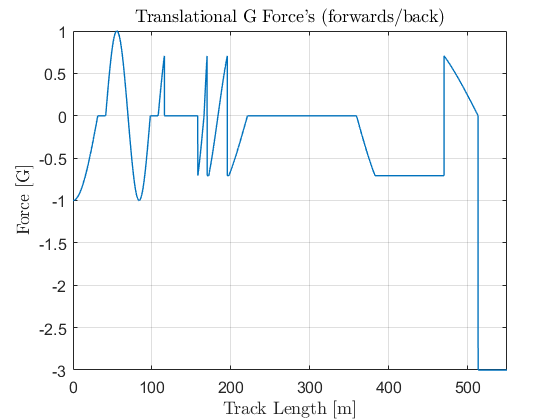


% Plotting X G forces (forward and backwards relative to motion)
plot([Gx2 Gx3 Gx4 Gx5 Gx6 Gx7 Gx8 Gx9 Gx10 Gx11 Gx12 Gx13 Gx14 Gx15 Gx16 Gx17 Gx18 Gx19],"LineWidth",1)
title("Translational G Force's (forwards/back)")
set(gca,'FontSize',12)
xlabel("Track Length [m]")
ylabel("Force [G]")
xlim([0 55000])
grid on
xticklabels([0 100 200 300 400 500])
hold off

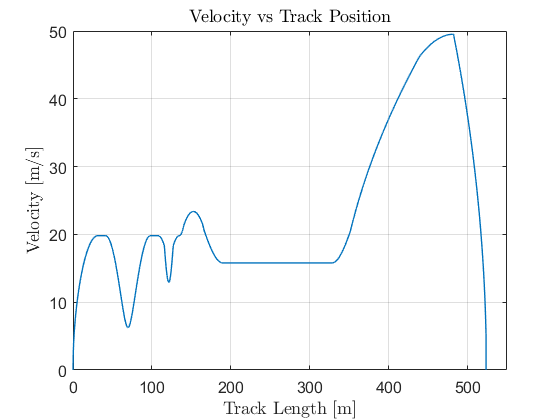


% Plotting velocity relative to position on the track
plot([vel2 vel3 vel4 vel5 vel6 vel7 vel8 vel9 vel10 vel11 vel12 vel13 vel14 vel15 vel16 vel17 vel18 vel19],"LineWidth",1)
title("Velocity vs Track Position")
set(gca,'FontSize',12)
xlabel("Track Length [m]")
ylabel("Velocity [m/s]")
grid on
xlim([0 55000])
xticklabels([0 100 200 300 400 500])
hold off

function [x, y, z, vel, Gx, Gy, Gz] = section1(xI,yI,zI,radius)
    % turning down after parabolic section
    theta = linspace(pi/2,pi/4,392);
    g = 9.81;
    x = radius.*cos(theta) + xI;
    y = theta.*0 + yI;
    z = radius.*sin(theta) + zI - radius;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = 3*cos(pi/2 - theta) - 2;
    Gx = cos(theta);
    Gy = theta .* 0;
end
function [x, y, z, vel, Gx, Gy, Gz] = sectionDown(xI,yI,zI,radius)
    % turning down after banked turn
    theta = linspace(pi/2,3*pi/4,2356);
    g = 9.81;
    x = radius.*cos(theta) + xI;
    y = theta.*0 + yI;
    z = radius.*sin(theta) + zI - radius;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = -((vel.^2)./(g * radius)) + sin(theta);
    Gx = cos(theta);
    Gy = theta .* 0;
end
function [x, y, z, vel, Gx, Gy, Gz] = section2(xI,yI,zI)
    % circular section, G's occur perpendicular to cart, vert -> flat
    theta = linspace(pi,3*pi/2,3141);
    radius = 20;
    g = 9.81;
    x = radius.*cos(theta) + radius;
    y = theta.*0 + yI;
    z = radius.*sin(theta) + zI;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = ((vel.^2)./(g * radius)) - sin(theta);
    Gx = cos(theta);
    Gy = theta .* 0;
end
function [x, y, z, vel, Gx, Gy, Gz] = section3(xI,yI,zI,L)
    % linear section, 1G downwards, propogates in the x direction 
    t = linspace(0,L,L*100);
    g = 9.81;
    x = t + xI;
    y = t.*0 + yI;
    z = t.*0 + zI;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = t .* 0 + 1;
    Gx = t .* 0;
    Gy = t .* 0;
end
function [x, y, z, vel, Gx, Gy, Gz] = section4(xI,yI,zI,radius)
    % circular section, G's occur perpendicular to cart, 45 degree to flat
    theta = linspace(3*pi/4,pi/2,2356);
    g = 9.81;
    x = radius.*cos(theta) + xI + 21.2132;
    y = theta.*0 + yI;
    z = radius.*sin(theta) + zI - 21.2132;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = -((vel.^2)./(g * radius)) + sin(theta);
    Gx = cos(theta);
    Gy = theta .* 0;
end
function [x, y, z, vel, Gx, Gy, Gz] = bankedTurn(xI, yI, zI, vel_in, theta)
    % banked turn, G's in all cartesian directions
    g = 9.81;
    thetaR = deg2rad(theta);
    r = ((vel_in)^2 / g) * cot(thetaR);
    t = linspace(-pi/2,pi/2,13817);
    Gx = t.*0;
    Gy = t.*0;
    Gz = t.*0 + 1./cos(thetaR);
    x = r.*cos(t) + xI;
    y = r.*sin(t) + yI + r;
    z = t.*0 + zI;
    vel = sqrt(2 .* g .* (125 - z));
end
function [x,y,z,V,Gx,Gy,Gz] = loopPath(xI,yI,zI,r,prop)
    %% Setup
    % Note, this currently only calculated velocity correctly
    % if the path is one full loop. I need to add the calculations
    % for the velocity vector for a partial loop.
    h0 = 125; % [m] initial height
    m = 100;  % [kg] particle mass
    g = 9.81; % [m/s^2] gravity
    t = linspace(-pi/2,(prop.*2.*pi)-pi./2,5654);
    %% calculating positions
    x = xI + r.*cos(t);
    z = zI + r + r.*sin(t);
    y = yI + 0.*t;         % If you change t to be multiplied by a nonzero number it becomes a helix
    %% velocity and G force calculations
    V = t.*0 + sqrt(2*g*(h0-z));
    N = m*((-sin(t)*g)+((V.^2)/r));
    Gz = t.*0 + N/(m*g);
    Gx = cos(t);
    Gy = t.*0;
    %% output
end
function [x, y, z, vel, Gx, Gy, Gz] = launch(xI,yI,zI,radius)
    % circular section, creates platform for parabolic section
    theta = linspace(3*pi/2,7*pi/4,785);
    g = 9.81;
    x = radius.*cos(theta) + xI;
    y = theta.*0 + yI;
    z = radius.*sin(theta) + zI + radius;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = ((vel.^2)./(g * radius)) - sin(theta);
    Gx = cos(theta);
    Gy = theta .* 0;
end
function [x, y, z, vel, Gx, Gy, Gz] = launch2(xI,yI,zI,radius)
    % circular section, valley
    theta = linspace(3*pi/2,7*pi/4,1178);
    g = 9.81;
    x = radius.*cos(theta) + xI;
    y = theta.*0 + yI;
    z = radius.*sin(theta) + zI + radius;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = ((vel.^2)./(g * radius)) - sin(theta);
    Gx = cos(theta);
    Gy = theta .* 0;
end
function [x, y, z, vel, Gx, Gy, Gz, vf] = Parabola(v0,pos0)
    %% Setup of variables and vectors
    t = linspace(0,10,4240);
    g = 9.81;
    x = ones(1,length(t)).*4200; % filling with large values
    y = ones(1,length(t)).*4200; % to be trimmed later
    z = ones(1,length(t)).*4200;
    x(1) = pos0(1);
    y(1) = pos0(2);
    z(1) = pos0(3);
    i = 2;
    %% Calculating path with kinematics
    while i <= length(t)
        x(i) = (v0(1)*t(i))+x(1);
        y(i) = (v0(2)*t(i))+y(1);
        z(i) = ((v0(3)*t(i))-(0.5*g*t(i)*t(i)))+z(1);
        if z(i) <= z(1)
            i = length(t);
        end
        i = i + 1;
    end
    %% Trimming position vectors
    x = x(x ~= 4200);   % output, [meters]
    y = y(y ~= 4200);   % output, [meters]
    z = z(z ~= 4200);   % output, [meters]
    vel = sqrt(2*g.*(125-z));
    Gz = t .* 0;
    Gx = t .* 0;
    Gy = t .* 0;
    % z(end) = z(1);
    vf = [v0(1) v0(2) -v0(3)];  % output, [m/s]
end
function [x, y, z, vel, Gx, Gy, Gz] = landing1(xI,yI,zI,radius)
    % circular section, platform for parabolic landing
    theta = linspace(5*pi/4,3*pi/2,785);
    g = 9.81;
    x = radius.*cos(theta) + xI + 7.0711;
    y = theta.*0 + yI;
    z = radius.*sin(theta) + zI + 7.0711;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = ((vel.^2)./(g * radius)) - sin(theta);
    Gx = cos(theta);
    Gy = theta .* 0;
end
function [x, y, z, vel, Gx, Gy, Gz] = landing2(xI,yI,zI,radius)
    % circular section, circular valley
    theta = linspace(5*pi/4,3*pi/2,1178);
    g = 9.81;
    x = radius.*cos(theta) + xI + 10.6066;
    y = theta.*0 + yI;
    z = radius.*sin(theta) + zI + 10.6066;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = ((vel.^2)./(g * radius)) - sin(theta);
    Gx = cos(theta);
    Gy = theta .* 0;
end
function [x, y, z, vel, Gx, Gy, Gz] = landing3(xI,yI,zI,radius)
    % circular section, landing for decline
    theta = linspace(7*pi/4,3*pi/2,4319);
    g = 9.81;
    x = radius.*cos(theta) + xI - 38.8909;
    y = theta.*0 + yI;
    z = radius.*sin(theta) + zI + 38.8909;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = ((vel.^2)./(g * radius)) - sin(theta);
    Gx = cos(theta);
    Gy = theta .* 0;
    z(end) = 0;
end
function [x, y, z, vel, Gx, Gy, Gz] = braking(xI,yI,zI,velI)
    % linear section, 1G downwards, propogates in the x direction, braking
    % (3g's in the negative x direction)
    t = linspace(0,41.2,4120);
    g = 9.81;
    x = -t + xI;
    y = t.*0 + yI;
    z = t.*0 + zI;
    accel = -3 * g;
    vel = sqrt(velI^2 + 2. * accel .* t);
    vel(end) = 0;
    Gz = t .* 0 + 1;
    Gx = t .* 0 - 3;
    Gy = t .* 0;
end
function [x, y, z, vel, Gx, Gy, Gz] = linearDown(xI,yI,zI,L)
    % simple linear decline
    t = linspace(0,L,L*100);
    g = 9.81;
    x = t + xI;
    y = t.*0 + yI;
    z = -t + zI;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = t .* 0 + sqrt(2)/2;
    Gx = t .* 0 - sqrt(2)/2;
    Gy = t .* 0;
end
function [x, y, z, vel, Gx, Gy, Gz] = linearDown2(xI,yI,zI,L)
    % simple linear decline
    t = linspace(0,L,L*100);
    g = 9.81;
    x = -t + xI;
    y = t.*0 + yI;
    z = -t + zI;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = t .* 0 + sqrt(2)/2;
    Gx = t .* 0 - sqrt(2)/2;
    Gy = t .* 0;
end
function [x, y, z, vel, Gx, Gy, Gz] = linearUp(xI,yI,zI,L)
    % simple linear incline
    t = linspace(0,L,L*100);
    g = 9.81;
    x = t + xI;
    y = t.*0 + yI;
    z = t + zI;
    vel = sqrt(2 .* g .* (125 - z));
    Gz = t .* 0 + sqrt(2)/2;
    Gx = t .* 0 - sqrt(2)/2;
    Gy = t .* 0;
end